# BME 2740 Interactive Lecture 13

# By: Dr. Asad Mirza

# Adapted From: Dr. Ilmar Tamames

## Central Euler Method

#### Recalling The Midpoint Rule

We have examined forward and backward integration schemes.

Nothing prevents us from using a “central” scheme.

To derive it you first need to do the Taylor Series for the forward point $x_k +h$


$$f\left(x_k +h\right)=\frac{f\left(x_k \right)}{0!}+f^{\prime } \left(x_k \right)\frac{h}{1!}+\ldotp \ldotp \ldotp$$


Then the same for the backward point $x_k -h$


$$f\left(x_k -h\right)=\frac{f\left(x_k \right)}{0!}-f^{\prime } \left(x_k \right)\frac{h}{1!}+\ldotp \ldotp \ldotp$$


Assuming we cut it off after the first derivative...

Subtract the backward from the forward, $O\left(h^2 \right)$ refers to the Big-O notation for the error of the left over terms.


$$f\left(x_k +h\right)-f\left(x_k -h\right)=\frac{2f^{\prime } \left(x_k \right)h}{1!}+O\left(h^2 \right)$$


Simplify


$$f\left(x_k +h\right)-f\left(x_k -h\right)=2hf^{\prime } \left(x_k \right)+O\left(h^2 \right)$$


Solve for $f^{\prime } \left(x_k \right)$


$$f^{\prime } \left(x_k \right)=\frac{f\left(x_k +h\right)-f\left(x_k -h\right)+O\left(h^2 \right)}{2h}$$


Simplify 


$$f^{\prime } \left(x_k \right)=\frac{f\left(x_k +h\right)-f\left(x_k -h\right)}{2h}+O\left(h\right)$$


If we ignore the error term we arrive at the formal version of the Central Euler Method


$$f^{\prime } \left(x_k \right)=\frac{f\left(x_k +h\right)-f\left(x_k -h\right)}{2h}$$


To convert it to MATLAB speak remember that $x_k +h$ means $x_{k+1}$ and $x_k -h$ means $x_{k-1}$


$$f^{\prime } \left(x_k \right)\sim \frac{f\left(x_{k+1} \right)-f\left(x_{k-1} \right)}{2h}$$


In MATLAB we can't have $x_{k-1}$ since at $k=1$ we would need to find $x_{1-1} =x_0$ and MATLAB doesn't have a zero index. 

Solution? Either shift all indexes forward by 1 or start our indexing at 2.

If we start indexing at 2 then we run into a bit of an issue.

Remember that we are solving for $f\left(x_{k+1} \right)=f\left(x_3 \right)$


$$f\left(x_{k+1} \right)=f\left(x_{k-1} \right)+f^{\prime } \left(x_k \right)*2h$$


Here:


$$f\;\left(x_{k-1} \right)=f\left(x_1 \right)$$



$$f\;\left(x_k \right)=f\left(x_2 \right)$$



$$f\;\left(x_{k+1} \right)=f\left(x_3 \right)$$


We know $f\left(x_1 \right)$ as that is our initial condition, $f\left(x_3 \right)$ is what we are trying to predict, $h$ is something we define.

However, $f\left(x_2 \right)$ is unknown? What we can do instead is apply the Forward Euler method for a single timestep to get an approximation of this value.


$$f\left(x_2 \right)=f\left(x_1 \right)+f^{\prime } \left(x_1 \right)*h$$


This can be applied to any ODE in MATLAB to solve it with the Central Euler Method.

- Uses information from both the forward and backward points to approximate the derivative, rather than using only the forward point as in Forward Euler

- The ODE tells us that y′(t)=f(t,y)y′(t)=f(t,y), we can write the formal Central Euler:

y_n+1=y_n−1 + 2 * h * f(t_n,y_n)

�

- Notice that this formula uses y_n−1 and y_n to calculate y_n+1�. Unlike Forward Euler, it requires two previous solution values.

#### Example 1

For $\frac{\mathrm{dy}}{\mathrm{dx}}=\sin \left(x\right)y,\;y{\left(0\right)}=1$

Write the MATLAB code to use the Central Euler Method to approximate for $x=0$ to $x=6$

Replace $\frac{\mathrm{dy}}{\mathrm{dx}}$ with our Central Euler Approximation


$$\frac{\left(y_{k+1} -y_{k-1} \right)}{2h}=\sin \left(x_k \right)y_k$$


Solve for $y_{k+1}$


$$y_{k+1} =2h*\sin \left(x_k \right)y_k +y_{k-1}$$


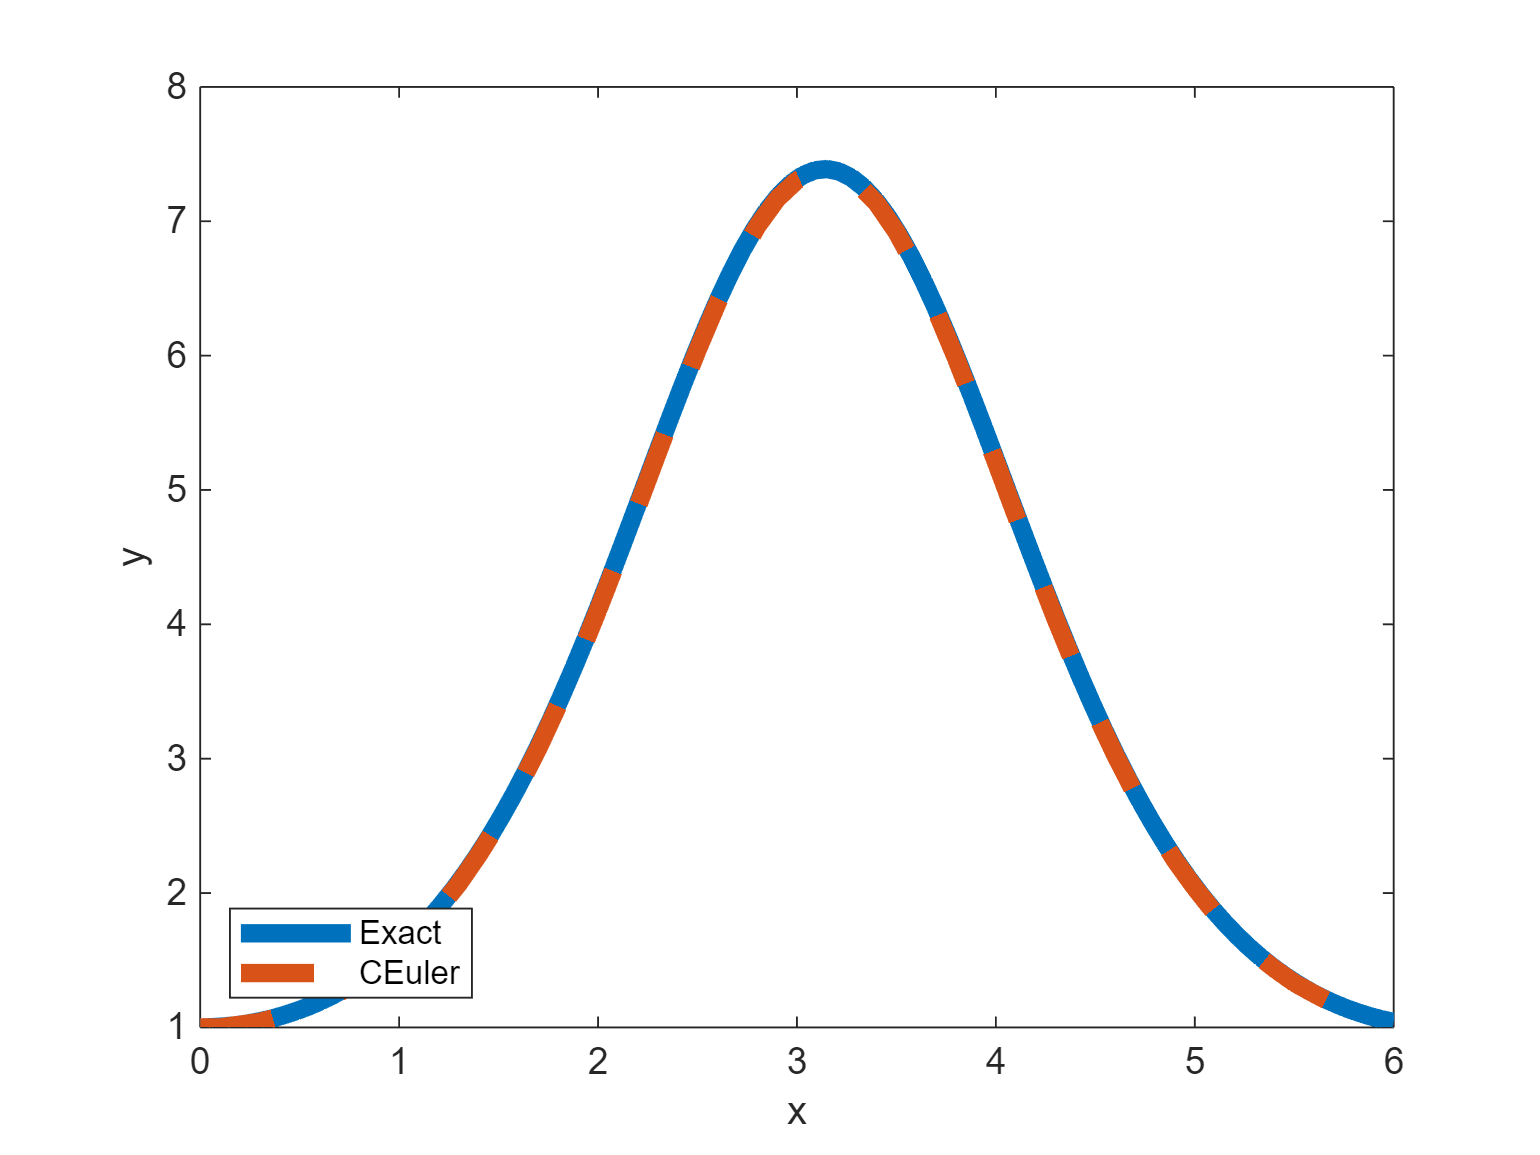

clear,clc,close all

% dy/dx = sin x * y
% y(0) = 1

% Set up
x0 = 1;                % Initial condition, y(0) = 1
h = .1;                % 1,.2,.1, .05, Step size
x = 0:h:6;             % Define solution vector, values from 0 to 6, increasing by 0.1 each time

y = zeros(1,length(x));% Preallocate memory for y


% % Step 1
% We make the first and 2nd index both IC since we start the loop at k=2

y(1)=x0;               % Apply Initial Condition
f=@(x,y) sin(x).*y;    % Set up function as anonymous


% % Step 2
% Use forward Euler to calculate the second point y(2) (for central difference)
y(2) = y(1) + h * f(x(1), y(1));
% The Central Euler Method requires two known solution values to calculate the next one. 
% You already know y(1), but you need y(2) to get started.


% % Step 3
% Central Euler, we start at k=2 so we don't run into having to figure out
% what y(1-1) or y(0) is.
for k=2:length(x)-1
     y(k+1)=2*h*f(x(k),y(k))+y(k-1);
     % k = 2 because you already have the first two solution values. 
     % It continues until the second-to-last point, calculating the next value each time.
end


% % Step 4
%Plotting
figure
% Make vector for exact solution plotting
xx=linspace(0,6,100);
% Exact solution
y_exact=@(x) exp(1-cos(x));
% Plot exact
plot(xx,y_exact(xx),'LineWidth',5)
hold on
% Plot Central Euler
plot(x,y,'--','LineWidth',5)
hold off
ylabel("y");
xlabel("x");
legend('Exact','CEuler',"Location","southwest")

Why don’t we just halve the step-size h rather than deal with this added complex equation?

## ODE Systems

When analyzing a physical system, the first task is generally to develop a mathematical description of the system in the form of differential equations. Typically a complex system will have several differential equations. The equations are said to be "coupled" if output variables (e.g., position or voltage) appear in more than one equation.

A system of ODEs can be expressed in terms of 1st order ODEs expressed in the general form:


$$\frac{dy_{{\left(1\right)}} }{dt}=f_1 \left(t,y_{{\left(1\right)}} ,y_{{\left(2\right)}} ,\ldotp \ldotp \ldotp ,y_{{\left(n\right)}} \right)$$



$$\frac{dy_{{\left(2\right)}} }{dt}=f_2 \left(t,y_{{\left(1\right)}} ,y_{{\left(2\right)}} ,\ldotp \ldotp \ldotp ,y_{{\left(n\right)}} \right)$$


...


$$\frac{dy_{{\left(n\right)}} }{dt}=f_n \left(t,y_{{\left(1\right)}} ,y_{{\left(2\right)}} ,\ldotp \ldotp \ldotp ,y_{{\left(n\right)}} \right)$$



$$y_{{\left(1\right)}} \left(0\right)=a,y_{{\left(2\right)}} \left(0\right)=b,\ldotp \ldotp \ldotp ,y_{{\left(n\right)}} \left(0\right)=z$$


where $f_1 ,f_2 ,\ldotp \ldotp \ldotp ,f_n$ represent linear or non-linear functions, and the a,b,...z are the initial values of the system.

#### Example 2 

Working with multiple diff equations!


$$\begin{array}{c}
\frac{dy_{{\left(1\right)}} }{dt}=5y_{{\left(1\right)}} -3y_{{\left(2\right)}} \\
\frac{dy_{{\left(2\right)}} }{dt}=-6y_{{\left(1\right)}} +2y_{{\left(2\right)}} 
\end{array}$$
 


$$y_{{\left(1\right)}} {\left(0\right)}=-1,y_{{\left(2\right)}} {\left(0\right)}=-2$$



$$Y{\left(3\right)}={\left[\begin{array}{c}
?\\
?
\end{array}\right]}$$


t=3^

For example, if


$$Y={\left[\frac{-1}{-2}\right]}$$


then the derivatives are

dy1/dt=5(−1)−3(−2)=1

dy2/dt=−6(−1)+2(−2)=2

 
$$\frac{\mathrm{dy}}{\mathrm{dx}}={\left[\begin{array}{c}
1\\
2
\end{array}\right]}$$


The same techniques of Forward Euler can be applied, but if our system of differential equations is now a vector,$\vec{f} \left(t,\vec{y} \right)$, that is, at every time-step, our algorithm will return 2 elements: $y_1$and $y_2$.

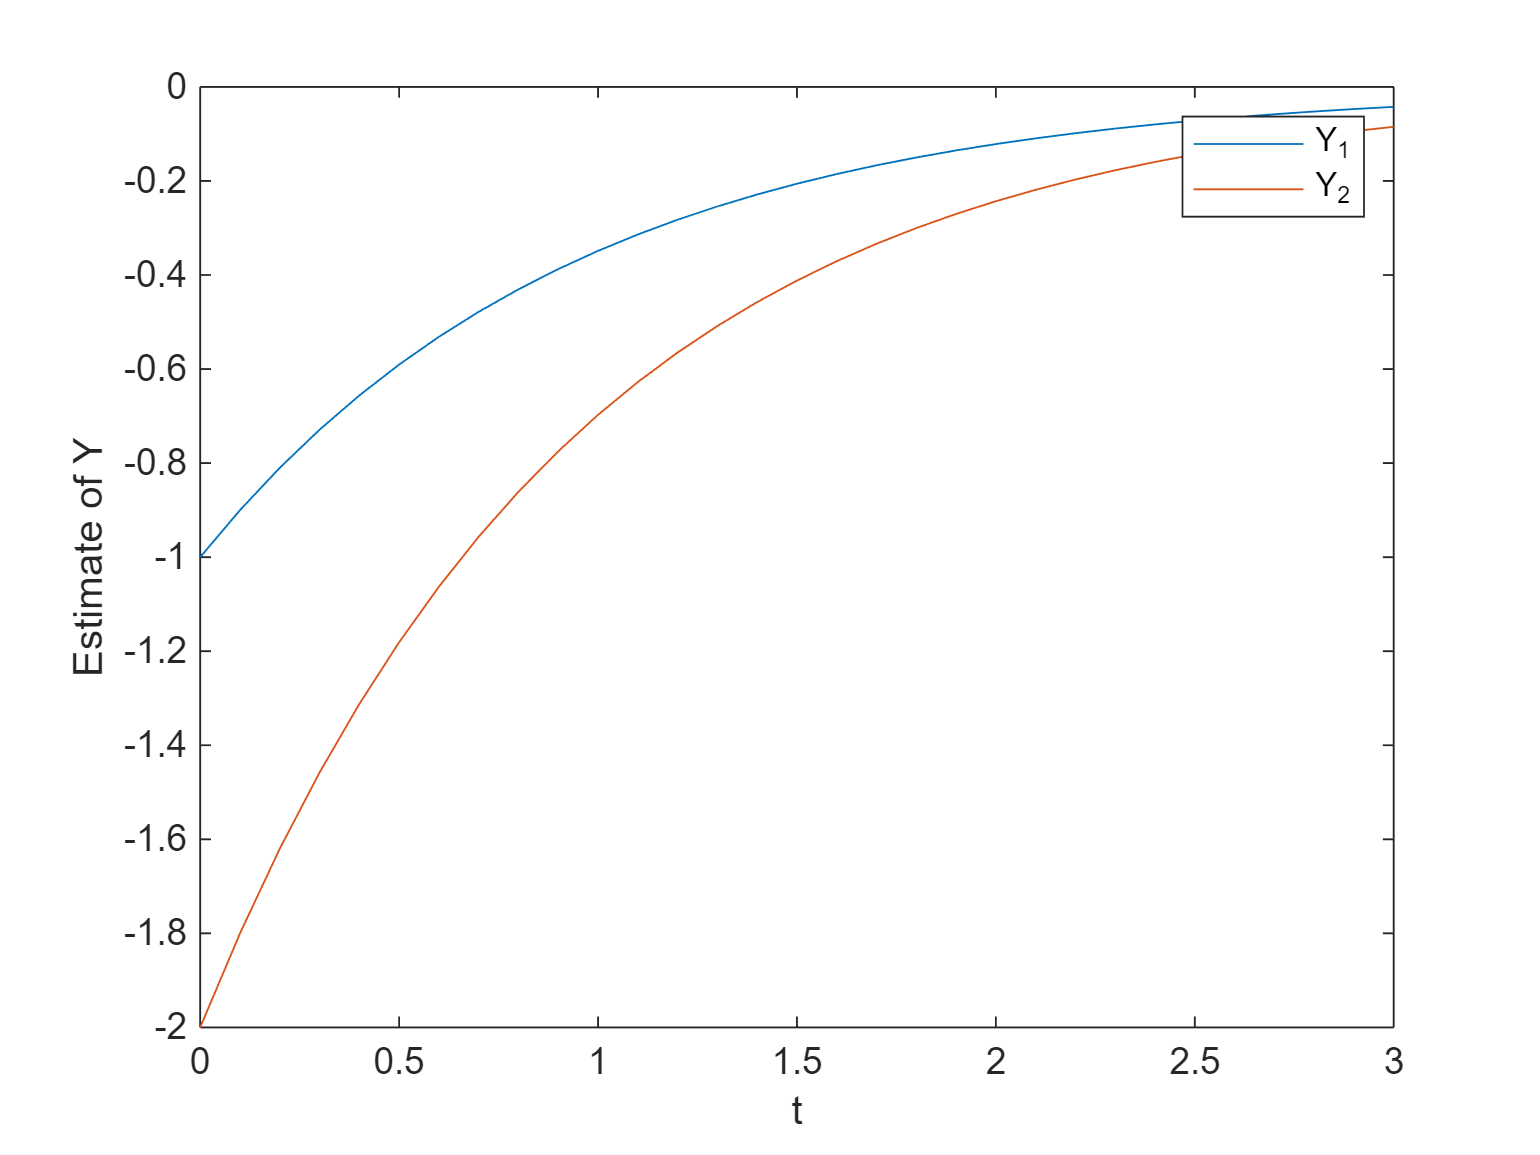

% Method 1: >>>> Using vector/matrix operations

% Coupled ODEs with FE
% Define the ODE System
% Remember that y = [y(1), y(2)]

% % Step 1 
% Define the diff equations
dy1 = @(t,y)  5*y(1) - 3*y(2); % derivative of y1
dy2 = @(t,y) -6*y(1) + 2*y(2); % derivative of y2
% Step size
h = 0.1;
% Time vector
t = 0:h:3; % 3 because we are looking for y(3), aka t=3

% % Step 2
% Initial conditions
y = zeros(2,length(t));
y(1,1) = -1;
y(2,1) = -2;
% ( You could also set both conditions at the same time
% Y(1:2,1)=[-1; -2]; )

% Forward Euler on the System of ODEs
for k=1:length(t)-1 % do not forget the -1!!!!!!
    % Method 1 - Leverage the fact that they are vectors
    % Ex: y(1:2,k) = [y(1,k); y(2,k)]
    % Meaning it's the k'th index of each variable
    y(1,k+1) = y(1,k) + h*dy1(t(k),y(1:2,k));
    %                             y(1:2,k) selects both current solution 
    %                               values, y1y1� and y2y2�.
    y(2,k+1) = y(2,k) + h*dy2(t(k),y(1:2,k));

end

% % Step 3
% Plot results
figure
% We can do this in 1 line since t is the same vector for both Y outputs.
% Y is a 2xN matrix that share the same t.
% You could also have plotted each individually 
% plot(t,Y(1,:))
% hold on
% plot(t,Y(2,:))
plot(t,y)
xlabel('t'); ylabel('Estimate of Y')
legend('Y_{1}','Y_{2}')

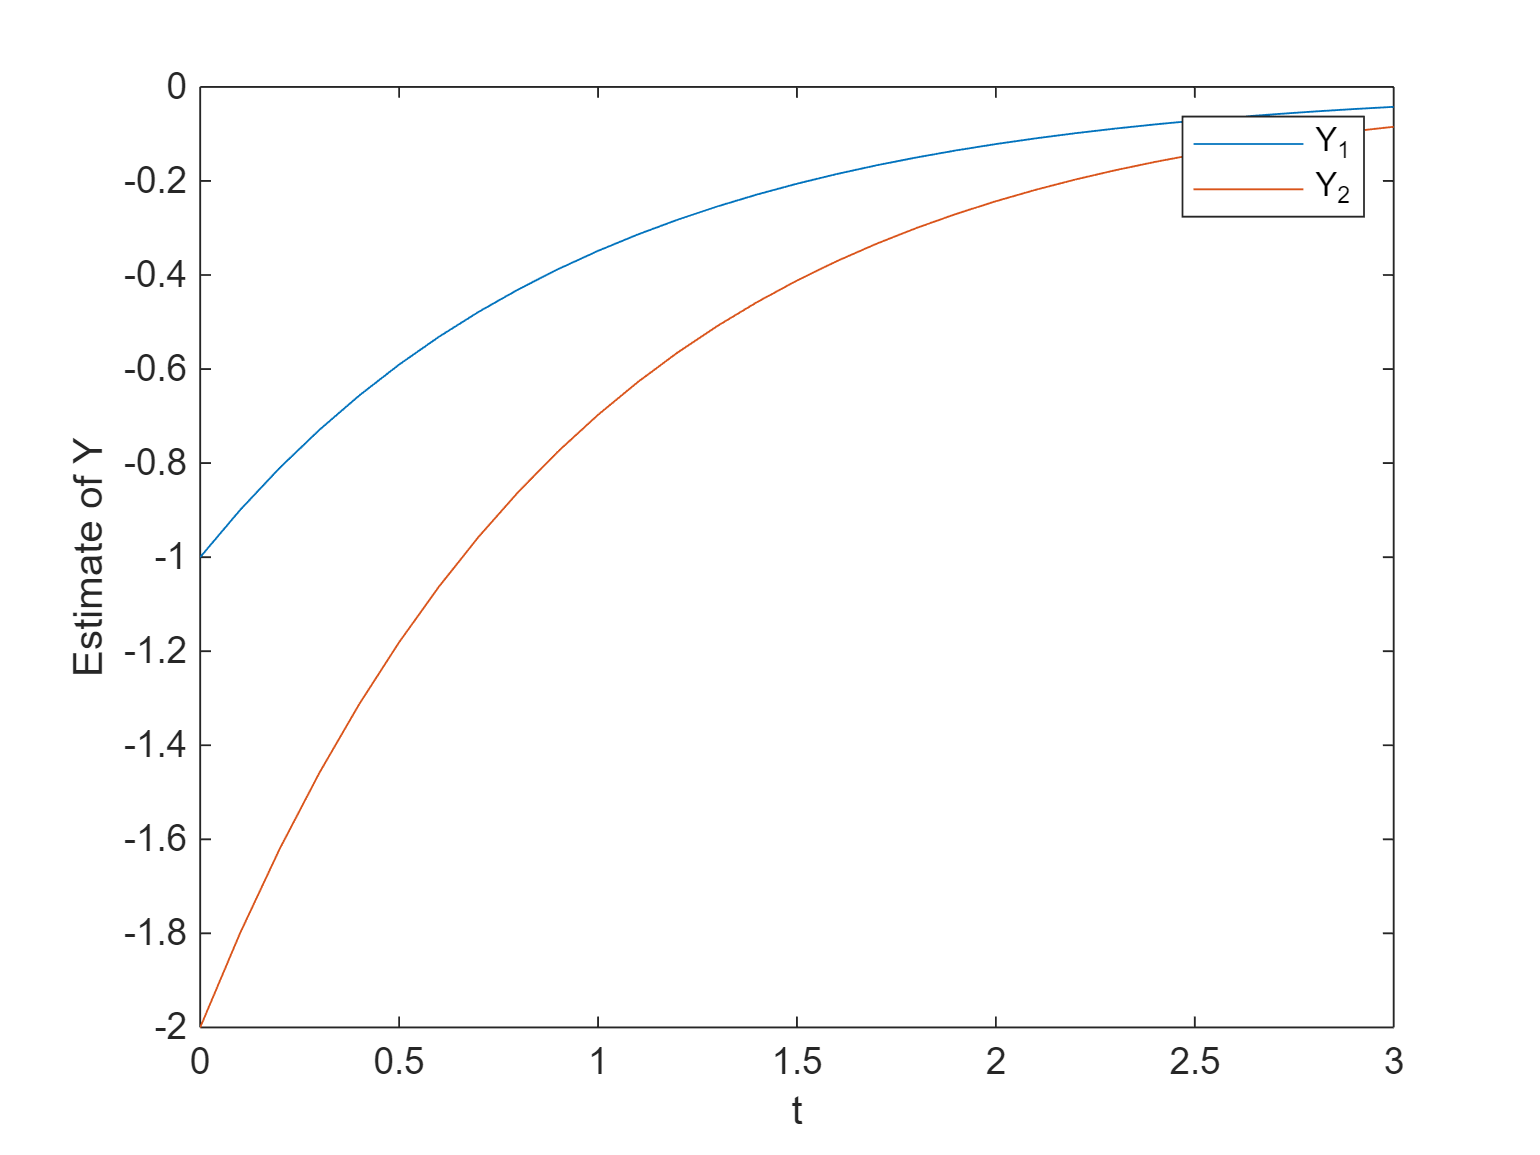

% Method 2 - Split it up based off the direct equations.
% Coupled ODEs with FE

% No functions set up!

% % Step 1
% Step size
h = 0.1;
% Time vector
t = 0:h:3;
% Store initial conditions into variables
y1 = -1;
y2 = -2;

% % Step 2
% Create plotting variables
y1_plot = zeros(1,length(t));
y2_plot = zeros(1,length(t));
y1_plot(1) = y1; % saves the initial value of y1�, which is −1.
y2_plot(1) = y2; % saves the initial value of y2�, which is −2.

%  y1 and y2 as the values we are currently calculating, 
%  y1_plot and y2_plot are notebooks that record every answer.

% % Step 3
% Forward Euler on the System of ODEs
for k = 1:length(t)-1
    % Store the current y1 and y2 values in temporary variables
    y1_new = y1 + h * (5*y1 - 3*y2);
    %                  ^ because dy1/dx = 5y1 - 3y2
    y2_new = y2 + h * (-6*y1 + 2*y2);
    %                  ^ because dy2/dx = -6y1 + 3y2
   
    y1 = y1_new;
    y2 = y2_new;
    
    % Store the results for plotting
    y1_plot(k+1) = y1;
    y2_plot(k+1) = y2;
end

% % Step 3
% Plot results
figure
plot(t, y1_plot)
hold on
plot(t, y2_plot)
xlabel('t'); ylabel('Estimate of Y')
legend('Y_{1}','Y_{2}')

#### Coupled ODE Systems

#### Scenario 1: Nature conservation

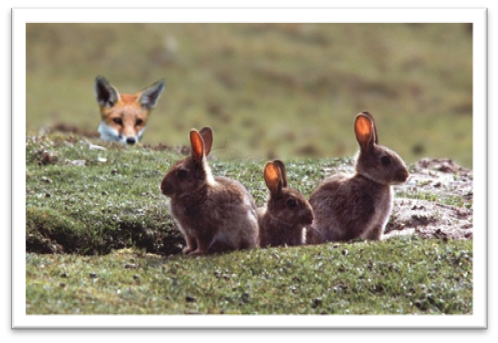

You are conducting R&D work for the nature conservation think tank, Friends of Nature, for a national state park. You would like to ensure a local group of rabbits and foxes maintain stable dynamics for five years with minimal intervention. To determine how to seed the initial populations (how many rabbits and foxes to release into the state park), you model the population dynamics with your knowledge of ecology:

a) A population of rabbits will increase by 120% per season if left undisturbed. (Breeding)

We can convert this sentence into a differential equation:

"A population of rabbits..per season" = $\frac{{\mathrm{dP}}_{\mathrm{rabbit}} }{\mathrm{dt}}$ 

"...will increase by 120%...if left undisturbed" = $1\ldotp 2P_{\mathrm{rabbit}}$


$$\frac{{\mathrm{dP}}_{\mathrm{rabbit}} }{\mathrm{dt}}=1\ldotp 2P_{\mathrm{rabbit}}$$


b) A population of foxes will decrease by 80% per season if left undisturbed. (Starving)

"A population of foxes..per season" = $\frac{{\mathrm{dP}}_{\mathrm{fox}} }{\mathrm{dt}}$ 

"...will decrease by 80%...if left undisturbed" = $-0\ldotp 8P_{\mathrm{fox}}$


$$\frac{{\mathrm{dP}}_{\mathrm{fox}} }{\mathrm{dt}}=-0\ldotp 8P_{\mathrm{fox}}$$


c) Foxes will eat rabbits when they encounter them, reducing their population by 60% per season in proportion to their joint encounters. (Predation)

We can update $\frac{{\mathrm{dP}}_{\mathrm{rabbit}} }{\mathrm{dt}}$ to account for this interaction term


$$\frac{{\mathrm{dP}}_{\mathrm{rabbit}} }{\mathrm{dt}}=1\ldotp 2P_{\mathrm{rabbit}} -0\ldotp 6P_{\mathrm{rabbit}} P_{\mathrm{fox}}$$


d) Fox populations will increase by 30% season in proportion to their joint encounters. (Consumption)

We can update $\frac{{\mathrm{dP}}_{\mathrm{fox}} }{\mathrm{dt}}$ to account for this interaction term


$$\frac{{\mathrm{dP}}_{\mathrm{foxes}} }{\mathrm{dt}}=-0\ldotp 8P_{\mathrm{fox}} +0\ldotp 3P_{\mathrm{rabbit}} P_{\mathrm{fox}}$$


Solve this system of ODEs for 20 seasons (5 years) with an initial population of rabbits of 2 and foxes of 1, assume they are in units of hundreds.

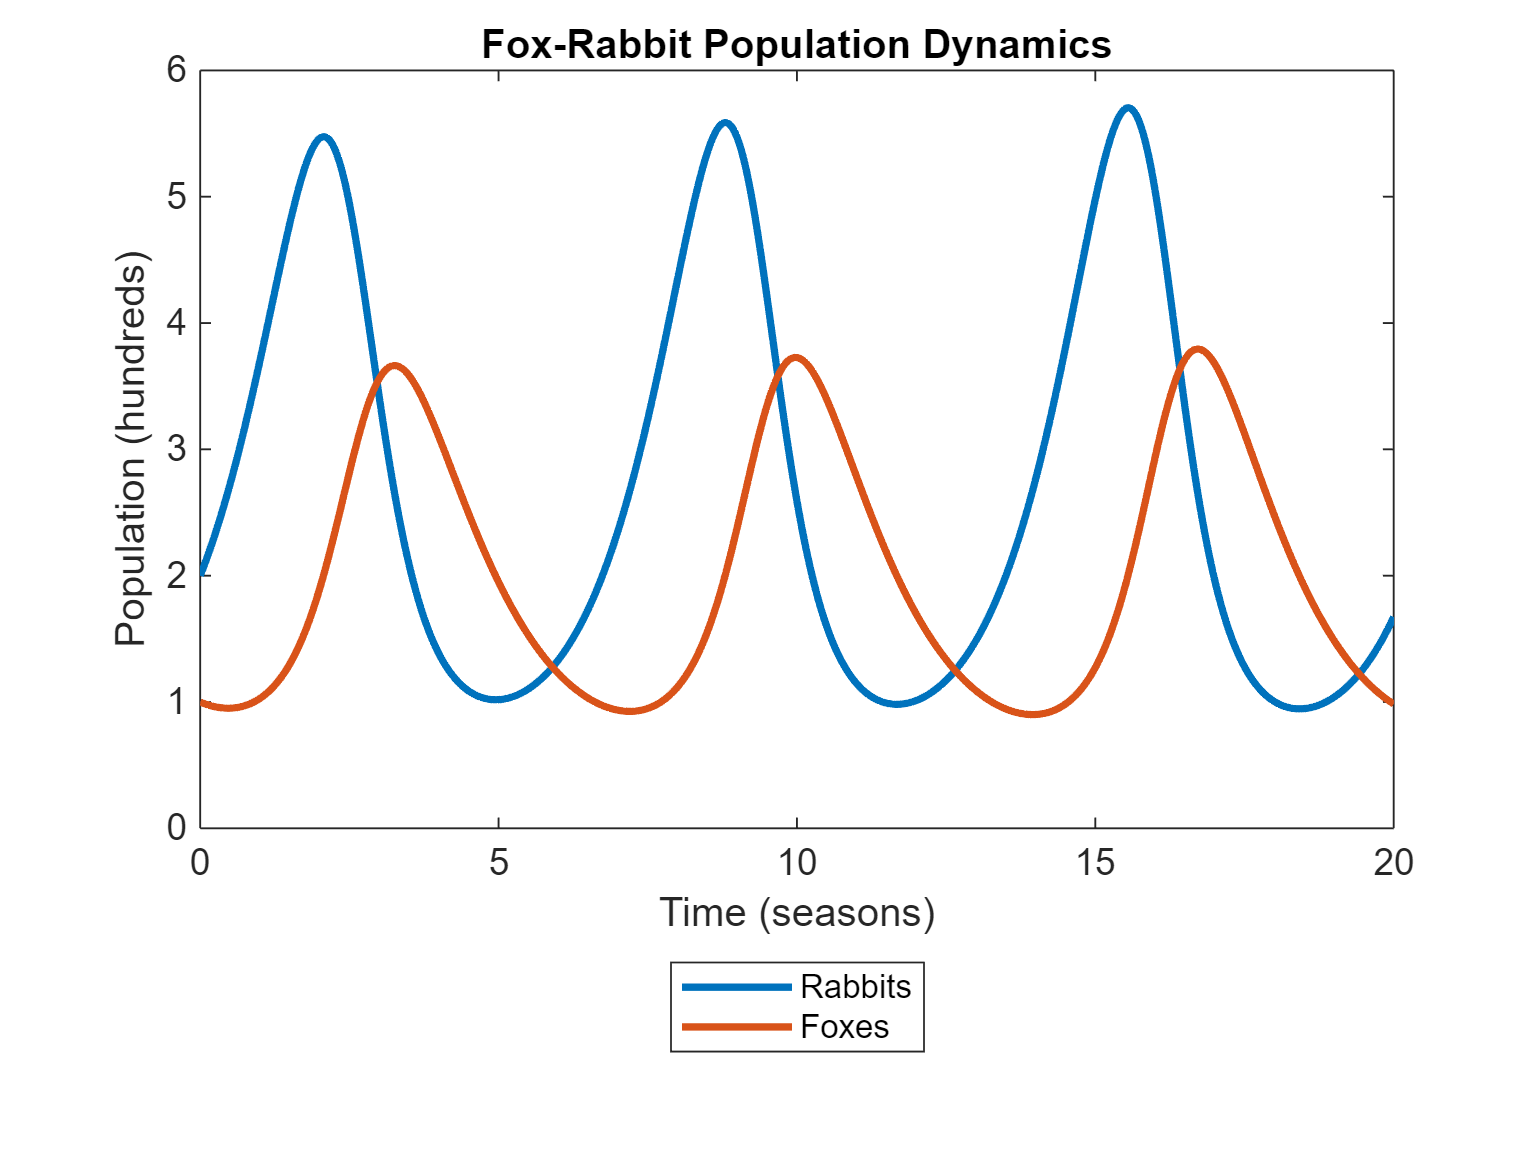

% Predator-Prey Model Simulation (Rabbits and Foxes)

% Initial populations in hundreds
P0rab = 2;  % Initial rabbit population (Hundreds)
P0fox = 1;  % Initial fox population (Hundreds)

% Simulation parameters
h = 0.01;           % Step size (one-tenth of a season)
t = 0:h:(4*5);     % Time vector (5 years, 4 seasons per year)

% Preallocate arrays for rabbit and fox populations
Prab = zeros(1, length(t));  % Array to store rabbit population over time
Pfox = zeros(1, length(t));  % Array to store fox population over time

% Set initial populations
Prab(1) = P0rab;  % Initial rabbit population at t = 0
Pfox(1) = P0fox;  % Initial fox population at t = 0

% Define the system of coupled ODEs
dPrab = @(pr, pf)  1.2 * pr - 0.6 * pr * pf;  % Rabbit population growth
dPfox = @(pr, pf) -0.8 * pf + 0.3 * pr * pf;  % Fox population growth

% Simulate the system using Euler's method
for k = 1:length(t)-1
    % Update rabbit population for the next time step
    Prab(k+1) = Prab(k) + h * dPrab(Prab(k), Pfox(k));
    % Update fox population for the next time step
    Pfox(k+1) = Pfox(k) + h * dPfox(Prab(k), Pfox(k));
end

% Plot the results
figure;
plot(t, Prab, t, Pfox, 'LineWidth', 2);
xlabel('Time (seasons)');
ylabel('Population (hundreds)');
legend('Rabbits', 'Foxes', 'Location', 'southoutside');
title('Fox-Rabbit Population Dynamics');

% SUMMARY

% Your model has two equations:
%  dR/ dt=1.2R−0.6RF

%  dF/dt=−0.8F+0.3RF


% Here, R is the rabbit population, F is the fox population, and RF represents their interaction.

% +1.2R: rabbits reproduce.

% −0.6RF: foxes eat rabbits, reducing their population.

% −0.8F: foxes die or decline because of starvation.

% +0.3RF: foxes benefit from eating rabbits.



#### Scenario 2: Lidocaine concentrations

The human malady of **ventricular arrhythmia** or irregular heartbeat is treated clinically using the drug **lidocaine**. To be effective, the drug has to be maintained at a bloodstream concentration of 1.5 milligrams per liter, but concentrations above 6 milligrams per liter are considered lethal in some patients. The actual dosage depends on the patient body weight.

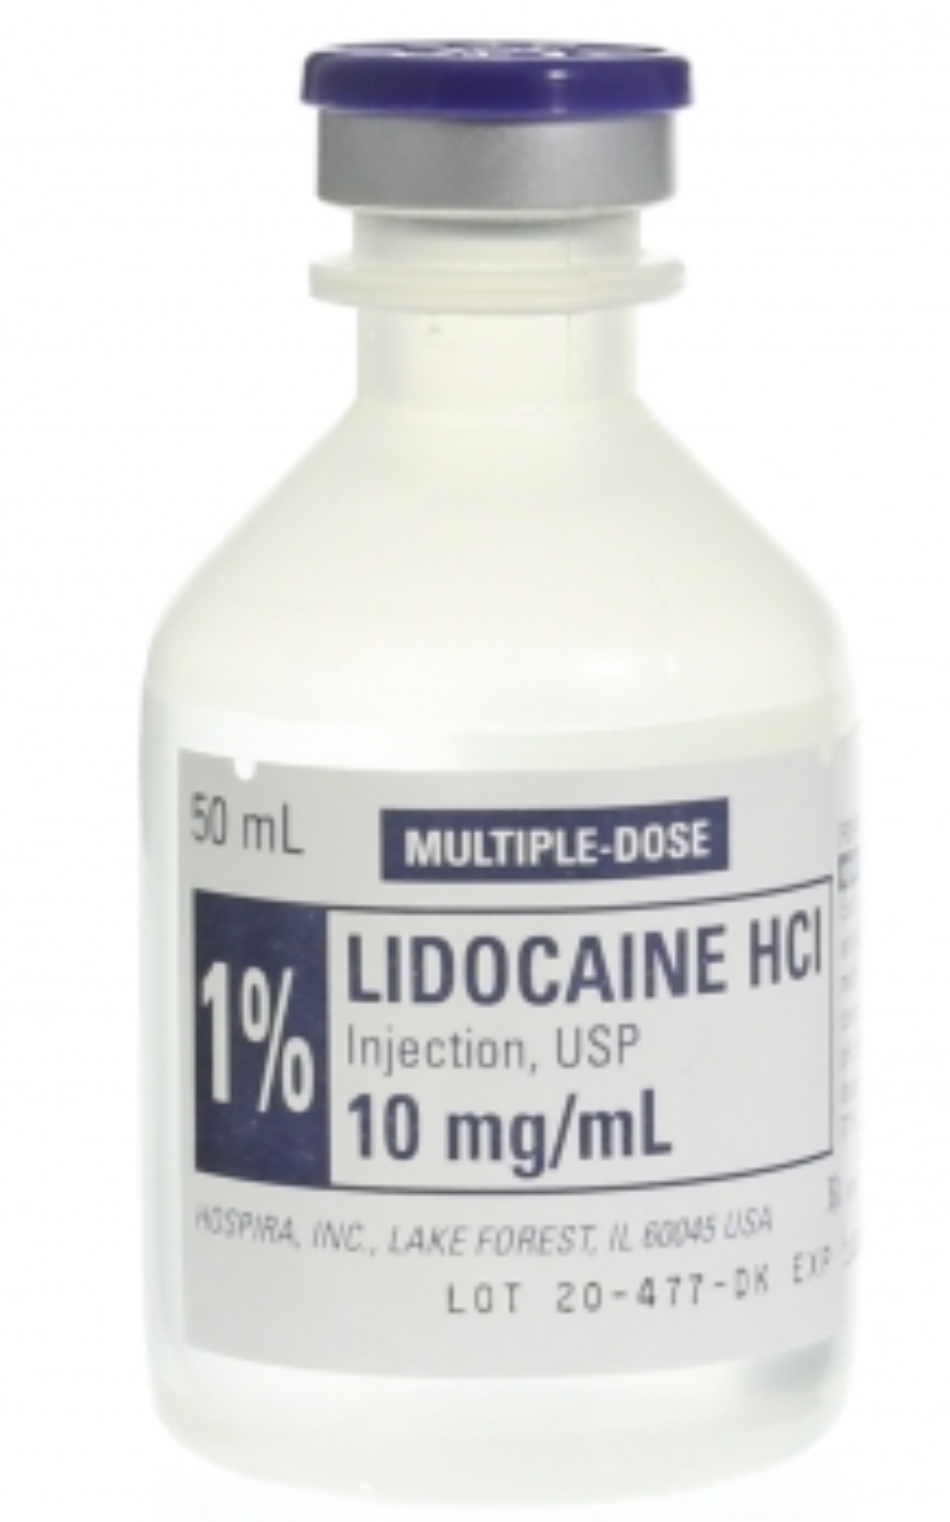

A typical set of equations, valid for special body weight only, appears below:


$$\frac{\mathit{dx}}{\mathit{dt}}=-0\ldotp 090x\left(t\right)+0\ldotp 038y\left(t\right)$$



$$\frac{\mathit{dy}}{\mathit{dt}}=0\ldotp 066x\left(t\right)-0\ldotp 038y\left(t\right)$$


Where $x$ is the amount of lidocaine in the bloodstream and $y$ is the amount of lidocaine in the body tissue.

If we have $x\left(0\right)=0$ and $y\left(0\right)=y_0$ as the injection dosage, plot the coupled system with $y_0 =15$ mg/kg during 150 minutes.

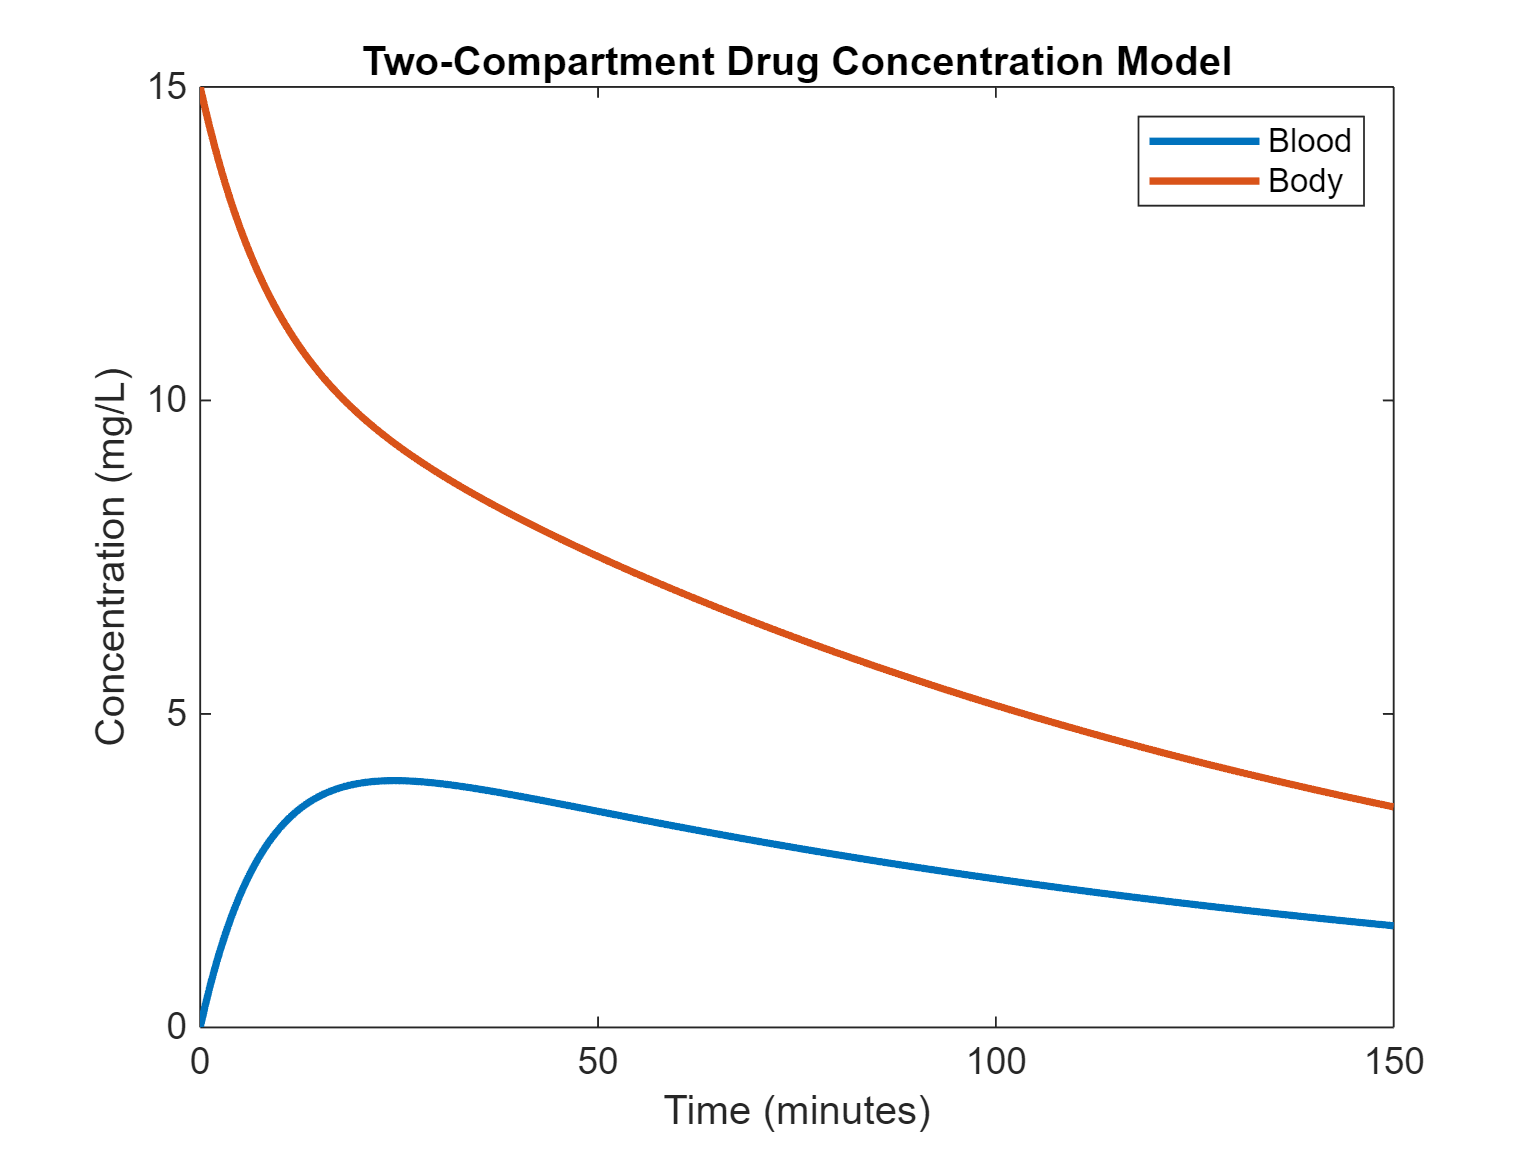

% Two-Compartment Model Simulation (Blood and Body Drug Concentration)
% Method 1
% Initial concentrations (mg/L)
P0blood = 0;   % Initial drug concentration in blood
P0body = 15;   % Initial drug concentration in body

% Simulation parameters
h = 0.1;           % Step size
t = 0:h:150;       % Time vector (in minutes)
% Preallocate arrays for blood and body drug concentrations
Pblood = zeros(1, length(t));  % Array to store blood concentration over time
Pbody  = zeros(1, length(t));   % Array to store body concentration over time

% Set initial concentrations
Pblood(1) = P0blood;  % Initial blood concentration at t = 0
Pbody(1) = P0body;    % Initial body concentration at t = 0

% Define the system of coupled ODEs
dPblood = @(pbl, pbo) -0.090 * pbl + 0.038 * pbo;  % Blood concentration change rate
dPbody = @(pbl, pbo)  0.066 * pbl - 0.038 * pbo;   % Body concentration change rate

% Simulate the system using Euler's method
for k = 1:length(t)-1
    % Update blood concentration for the next time step
    Pblood(k+1) = Pblood(k) + h * dPblood(Pblood(k), Pbody(k));
    % Update body concentration for the next time step
    Pbody(k+1) = Pbody(k) + h * dPbody(Pblood(k), Pbody(k));
end

% Plot the results
figure;
plot(t, Pblood, t, Pbody, 'LineWidth', 2);
xlabel('Time (minutes)');
ylabel('Concentration (mg/L)');
legend('Blood', 'Body', 'Location', 'northeast');
title('Two-Compartment Drug Concentration Model');

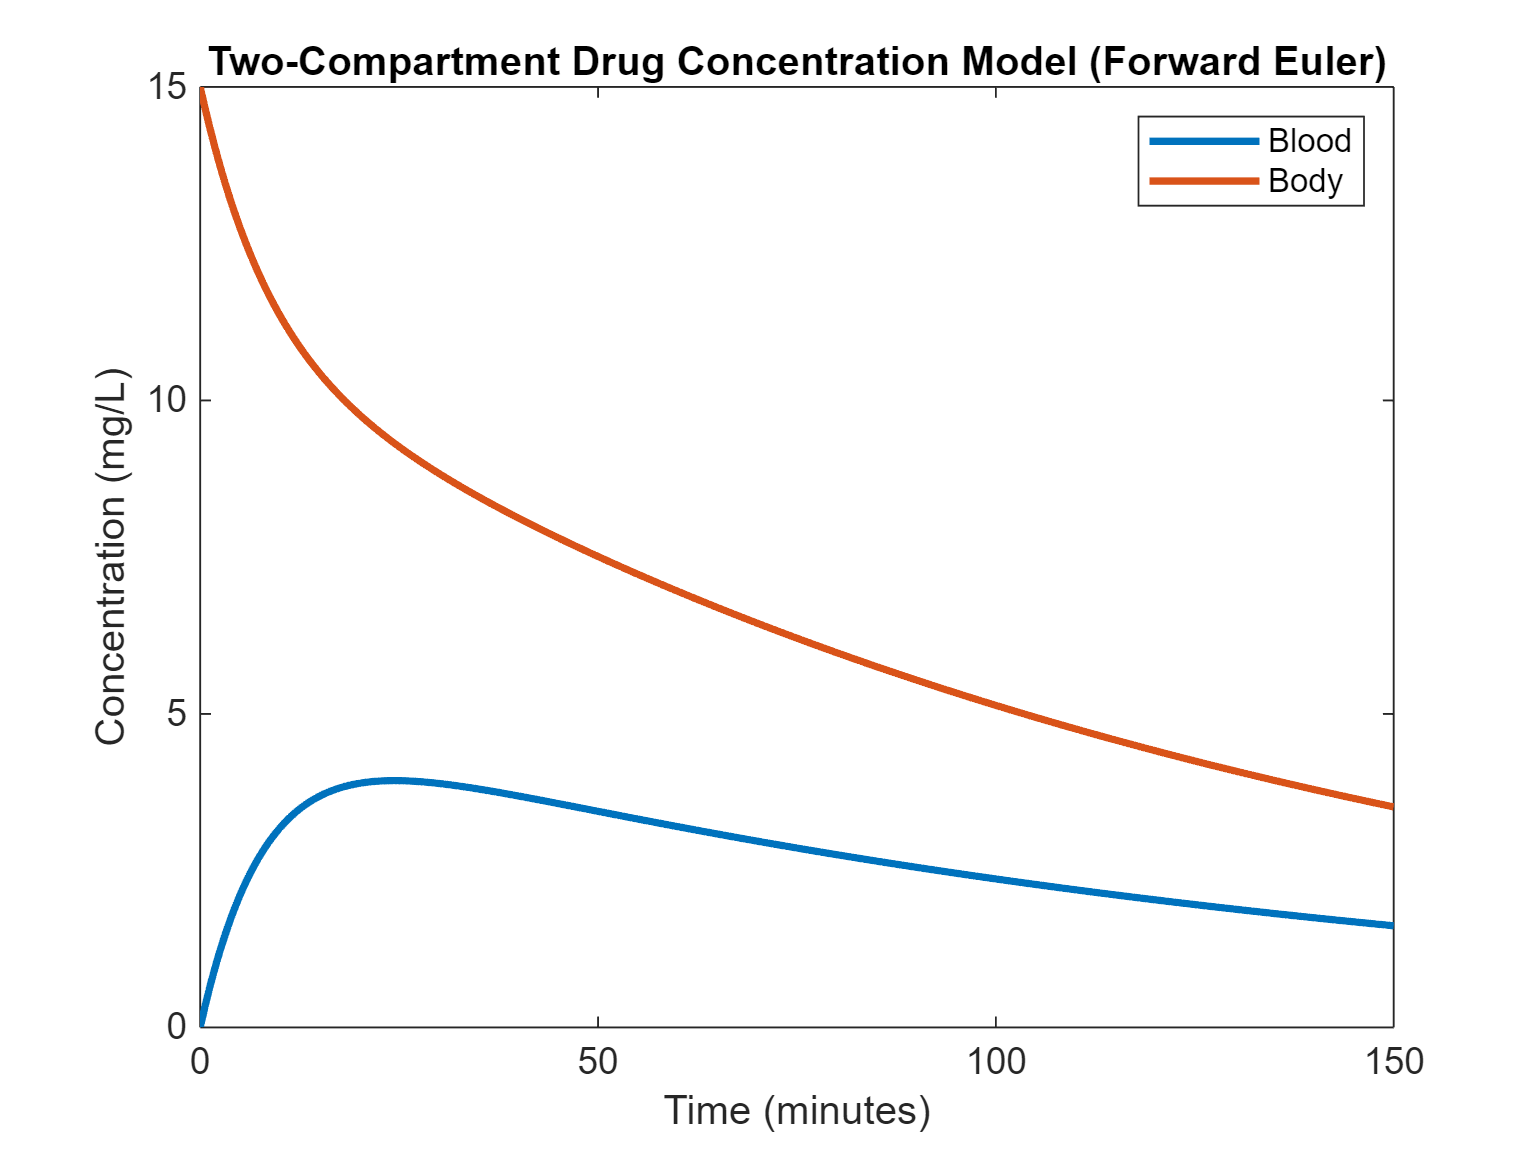

% Method 2

% Simulation parameters
h = 0.1;           % Step size
t = 0:h:150;       % Time vector (in minutes)

% Initial concentrations (mg/L)
P0blood = 0;   % Initial drug concentration in blood
P0body = 15;   % Initial drug concentration in body
% Define the system of coupled ODEs as a function handle
f = @(x) [-0.090 * x(1) + 0.038 * x(2);  % Change in blood concentration
           0.066 * x(1) - 0.038 * x(2)]; % Change in body concentration

% Preallocate array for storing Lidocaine concentrations over time
Lido = zeros(2,length(t));
Lido(1:2,1)=[P0blood;P0body];
% Simulate the system using Forward Euler method
for k = 1:length(t)-1
    Lido(:,k+1) = Lido(:,k) + h * f(Lido(:,k));  % Update concentrations
end

% Plot the results
figure;
plot(t, Lido(1,:), t, Lido(2,:), 'LineWidth', 2);
xlabel('Time (minutes)');
ylabel('Concentration (mg/L)');
legend('Blood', 'Body', 'Location', 'northeast');
title('Two-Compartment Drug Concentration Model (Forward Euler)');

#### Scenario 3: Brine Tank Cascade

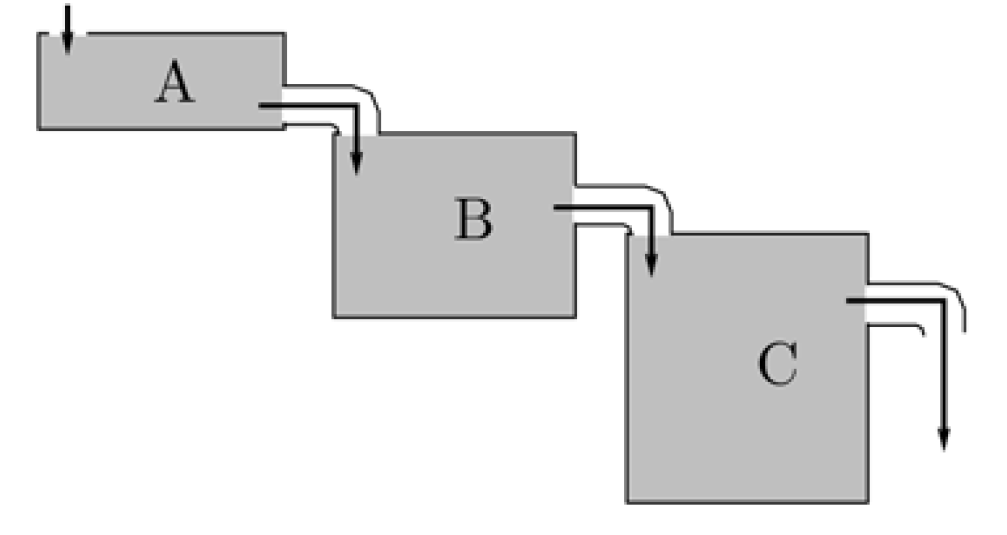

Fluid enters tank A at a rate r, drains from A to B at rate r, drains from B to C at rate r, then drains from tank C at rate r, with a uniform salt concentration within each tank. If the input to tank A is fresh water, and we denote variables x1, x2, and x3 as the salt concentration in each tank (mg/L), then for r=10 the input change in concentration. The system is defined below:


$$\frac{dx_1 }{\mathit{dt}}=-\frac{1}{2}x_1$$



$$\frac{dx_2 }{\mathit{dt}}=\frac{1}{2}x_1 -\frac{1}{4}x_2$$



$$\frac{dx_3 }{\mathit{dt}}=\frac{1}{4}x_2 -\frac{1}{6}x_3$$


Simulate this system with a step size of h=0.05 for the 60 seconds where all tanks start at 50 mg/L of salt.

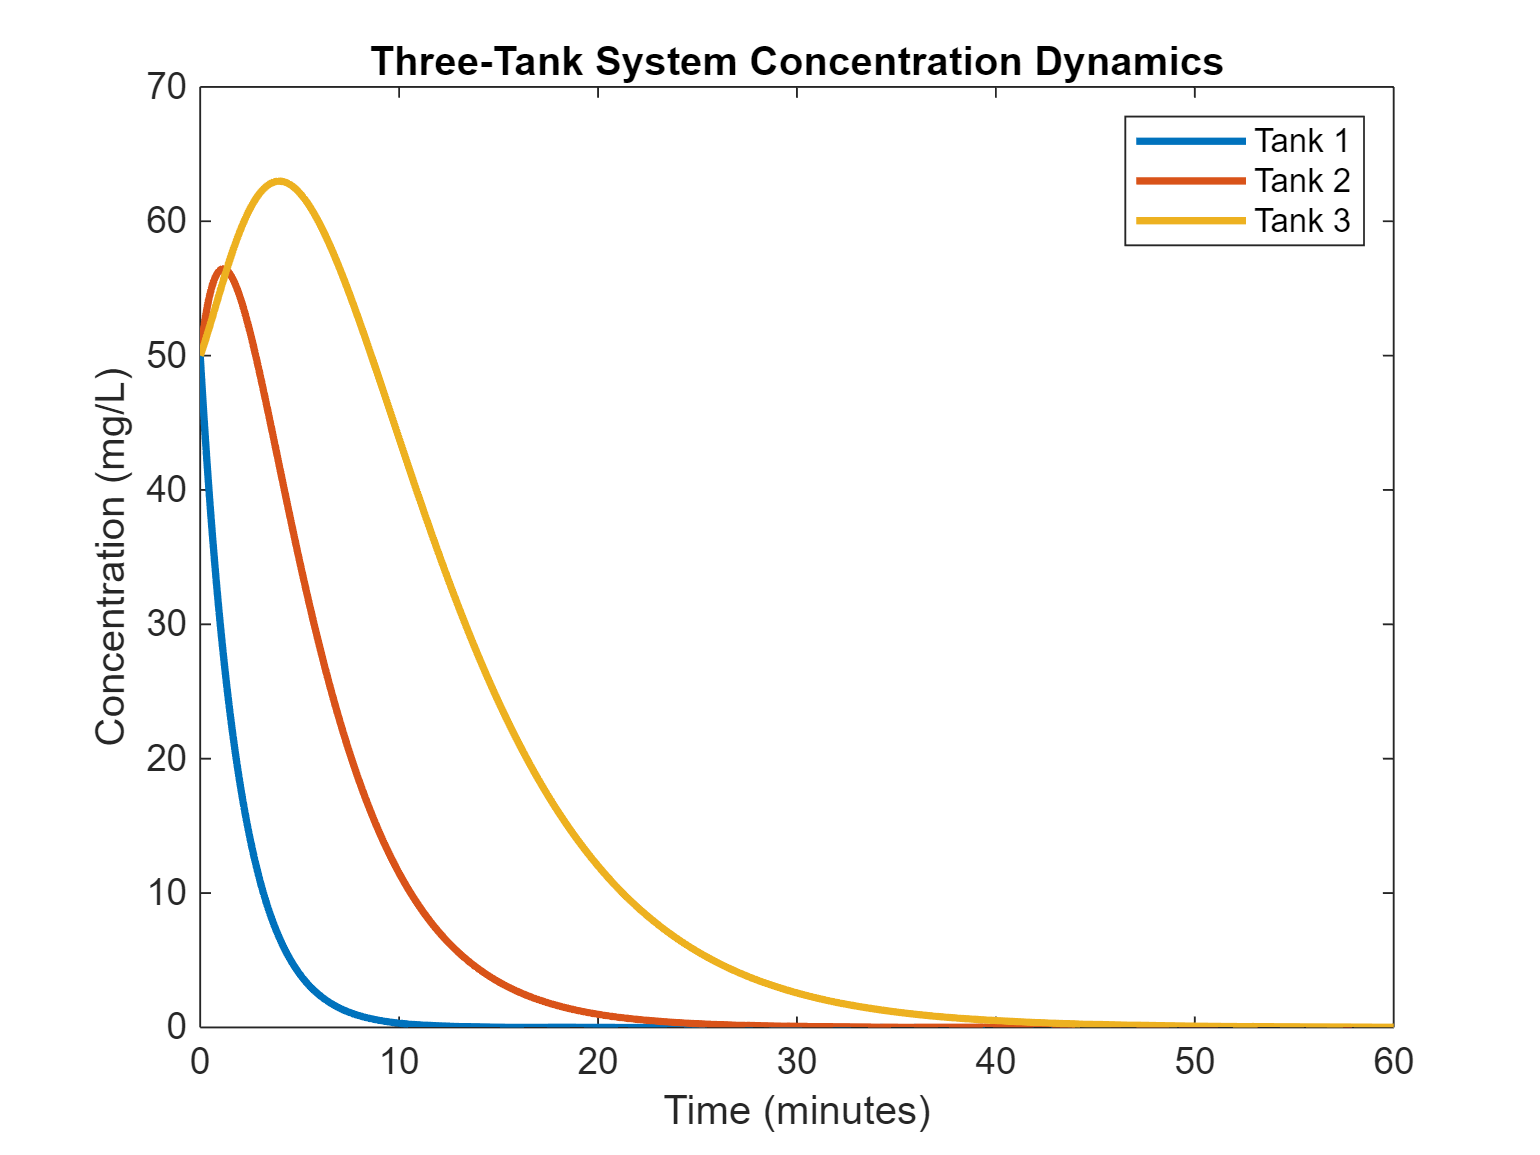

% Three-Tank System Simulation using Forward Euler Method

% Simulation parameters
h = 0.05;           % Step size
t = 0:h:60;         % Time vector (in minutes)

% Initial conditions for tank concentrations (assume all start at 50 units)
x = zeros(3, length(t));  % Preallocate matrix for concentrations
x(:,1) = [50; 50; 50];    % Initial concentrations in Tank 1, Tank 2, Tank 3

% Define the system of coupled ODEs for the tanks
f = @(x) [-0.5 * x(1); ...                     % Change in concentration for Tank 1
           0.5 * x(1) - 0.25 * x(2); ...       % Change in concentration for Tank 2
           0.25 * x(2) - (1/6) * x(3)];        % Change in concentration for Tank 3

% Simulate the system using the Forward Euler method
for k = 1:length(t)-1
    x(:,k+1) = x(:,k) + h * f(x(:,k));  % Update concentrations for the next time step
end

% Plot the results
figure;
plot(t, x(1,:), t, x(2,:), t, x(3,:), 'LineWidth', 2);
xlabel('Time (minutes)');
ylabel('Concentration (mg/L)');
legend('Tank 1', 'Tank 2', 'Tank 3', 'Location', 'northeast');
title('Three-Tank System Concentration Dynamics');